## Buck Boost

% Parametros de projeto
Vs = 30;
Vo = 20;
fs = 40 * 1e3;
P = 15;
delta_Vo = 0.1;
delta_Il = 0.3;
T = 1/fs;

% Calculo do duty cycle
% aux = (Vo/Vs);
% D = aux / (1 + aux)
D = Vo / (Vs + Vo)

D = 0.4000

% Carga 
R = (Vo^2)/P 

R = 26.6667

% Corrente média no indutor
iL = Vo / (R * (1 - D))

iL = 1.2500

% Corrente max e min no indutor
iL_min = iL - ((delta_Il * iL)/2)

iL_min = 1.0625

iL_max = iL + ((delta_Il * iL)/2)

iL_max = 1.4375

% iL RMS
iL_rms = sqrt(iL^2 + (delta_Il^2)/12)

iL_rms = 1.2530

% Calculo do indutor
L = (Vs * D * T) / (delta_Il * iL) % 

L = 8.0000e-04

% Calculo do capacitor
C = D / (delta_Vo * R * fs) % (D * Vo)  / (delta_Vo * Vo * R * fs)

C = 3.7500e-06

% Indutancia mininima para CCM
Lmin = (((1-D)^2)*R)/(2*fs)

Lmin = 1.2000e-04

if L > Lmin
    disp("L > Lmin: opera em CCM")
else
    disp("L < Lmin: nao opera em CCM")
end

L > Lmin: opera em CCM


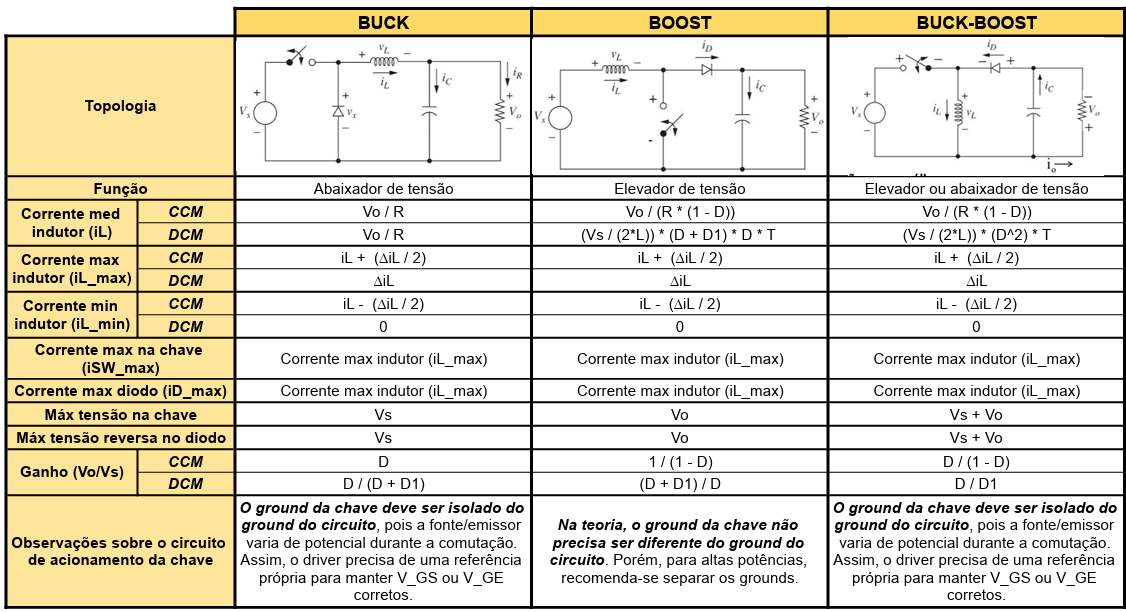

max_V_chave = Vs + Vo

max_V_chave = 50

max_i_chave = iL_max

max_i_chave = 1.4375

max_V_diodo = Vs + Vo

max_V_diodo = 50

max_i_diodo = iL_max

max_i_diodo = 1.4375

## Acionamento MOSFET IRF530

% Etapa 1: Definição dos parâmetros de operação do circuito e da tensão de acionamento:
Vds = max_V_chave; % Tensão dreno source
Id = iL_max; % corrente de dreno
Vsw = 15; % tensão de acionamento desejada
% D razão ciclica de acionamento
% R resistencia da carga
Vmicro = 3.3; % tensão de saida do micro / entrado do driver
% fs frequencia de chaveamento

% Etapa 2: Definição do MOSFET utilizado e obtenção dos dados do datasheet:
Rds = 0.16; % resisitencia entre dreno e source
Qg_max = 26e-9;% carga maxima do gate
Qgd_max = 11e-9; % carga maxima gate dreno
Qgs_max = 5.5e-9; % carga maxima gate source
Qds_min = 11e-9; % carga min dreno source 
Vth = 4; % tensão th de acionamento mosfet
Gfs = 5.1; % transcondutancia direta
Ciss_typ = 670e-12; % capacitancia de entrada tipica
Coss_typ = 250e-12; % capacitancia de saida tipica
Crss_typ = 60e-12; % capacitancia de transferencia reversa tipica
tr_typ = 34e-9; % tempo de subida tipico
tf_typ = 24e-9; % tempo de descida tipico
R_int = 1; % resistencia de gate interna

% Etapa 3: Cálculo das correntes de gate de acionamento e desligamento:
Igon1 = Qgs_max/tr_typ; % Corrente de gate para o acionamento com rise time considerando Qgmax
Igon2 = (Qgd_max + Qgs_max) / tr_typ; % Corrente de gate para o acionamento com rise time considerando Qgs+Qgd

Igoff1 = Qgs_max/tf_typ; % Corrente de gate para desligamento com fall time considerando Qgmax
Igoff2 = (Qgd_max + Qgs_max) / tr_typ; % Corrente de gate para desligamento com fall time considerando Qgs+Qgd


#### Etapa 4: Cáculo do resistor de gate:

O resistor de gate tem a função de limitar a velocidade de carga e descarga de Ciss -> limitar a corrente de acionamento do gate

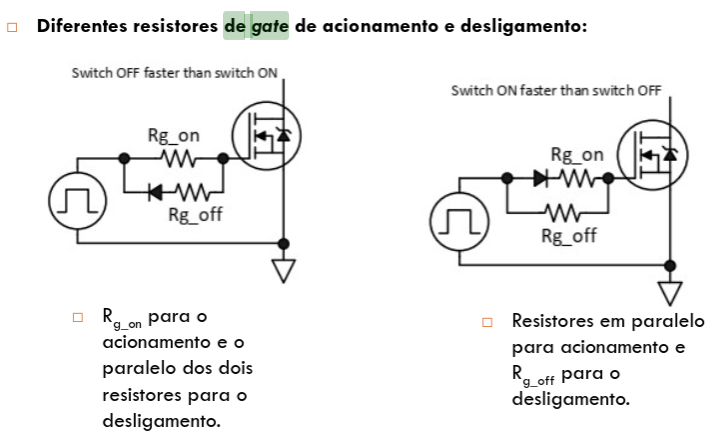

% Considerando a carga total do gate
Ron1 = (Vsw/Igon1) - R_int % Resistência do gate do acionamento

Ron1 = 91.7273

Roff1 = (Vsw/Igoff1) - R_int % Resistência do gate do desligamento

Roff1 = 64.4545

% Considerando a carga total do gate
Ron2 = (Vsw/Igon2) - R_int % Resistência do gate do acionamento

Ron2 = 29.9091

Roff2 = (Vsw/Igoff2) - R_int % Resistência do gate do desligamento

Roff2 = 29.9091

Cálculo dos tempos de comutação 

tdon -> Tempo de atraso ao crescimento da corrente de dreno

tri -> Tempo de crescimento da corrente de dreno

Na prática, se o tempo tri  calculado for menor que o tempo de comutação do

MOSFET dado no datasheet significa que a comutação estaria limitada pela

capacidade do MOSFET em lidar com as transições rápidas de corrente, já

que o tempo estimado foi menor que o mínimo que o componente

consegue atingir.

Ron = Ron2; % usar qual Ron?
tdon = (Ron + R_int) * Ciss_typ * log(Vsw/(Vsw-Vth))

tdon = 6.4230e-09

tri = (Ron + R_int) * Ciss_typ * log( (Gfs*(Vsw-Vth)) / ((Gfs*(Vsw-Vth)) - Id) )

tri = 5.3756e-10

Tempo de decréscimo da tensão de dreno

Vds_on = 0;
VGPL = Vth + (Id/Gfs); % Tensão de Plateau do MOSFET
tfv = (Ron + R_int) * Ciss_typ * log((Vds-Vds_on)/(Vsw-VGPL)) % Tempo de decréscimo da tensão de dreno

tfv = 3.1894e-08

% Como levar essa perda em conta na perda total?
Pon = 0.5 * Vds * Id * (tri + tfv) * fs % Perdas na entrada em condução

Pon = 0.0466

## Analise das perdas sem considerar o circuito de acionamento

P_chave_comut = 0.5 * Vds * Id * (tr_typ + tf_typ) * fs % potência média dissipada devido às comutações

P_chave_comut = 0.0834

P_chave_cond = (Id^2) * Rds

P_chave_cond = 0.3306

P_chave_total = P_chave_comut + P_chave_cond

P_chave_total = 0.4140

V_queda_diodo = 0.65; % MBR360
P_diodo_cond = V_queda_diodo * Id

P_diodo_cond = 0.9344

porcentagem_perda_chave = P_chave_total*100 / (P_chave_total+P_diodo_cond)

porcentagem_perda_chave = 30.7036

porcentagem_perda_diodo = P_diodo_cond*100 / (P_chave_total+P_diodo_cond)

porcentagem_perda_diodo = 69.2964

eficiencia_conversor = P*100 / (P + (P_chave_total+P_diodo_cond))

eficiencia_conversor = 91.7522